# MA 590 : Computational Inverse Problems

# Homework 4

Note: This runs really really slowly with all the graphing and looping, but it does run for me at least. 

## Problem 1

## (a)

For a logarithmic distribution of values of different regularization parameters $\alpha$ between $10^{-4}$ and 1, with $\sigma_i$ the singular values of $G$, $u_i$ the columns of $U$ in the singular value decomposition $G = U\Sigma V^T$, and $v_i$ the columns of $V$ in the singular value decomposition $G = U\Sigma V^T$,  we will calculate the filter factors


$$f_i = \frac{\sigma_i^2}{\sigma_i^2 + \alpha^2}\quad \quad (1)$$


along with the corresponding zeroth order Tikhonov solution


$$x_\alpha = \sum_{i=1}^{64} f_i \frac{u_i^Ty}{\sigma_i}v_i \quad \quad (2)$$


clear all
close all
clc

n = 64;

%The phillips.m function produces Phillips’ test problem, which is a
%discretization of a Fredholm integral equation of the first kind.
[G, y_true, x_true] = phillips(n);
[U,S,V] = svd(G);
singular_values = diag(S);

%We generate noisy data y adding a normally distributed perturbation
%to y_true with zero mean and standard deviation 10−4
y = y_true + 10^-4*randn(length(y_true),1);

%We use 50 logarithmically equally spaced points between 10^-4 and 10^0
alphas = logspace(-4,0);

x_tikhonov = zeros(n, length(alphas));

for jj = 1:length(alphas)
    
    %The filter factors change for each new choice of alpha. We use equation (1) to find them.
    filter_factors = singular_values.^2 ./ (singular_values.^2 + (alphas(jj))^2);
    
    %The loop below calculates the Tikhonov solution for a given alpha using equation (2). 
    for ii = 1:n
        
        x_tikhonov(:,jj) = x_tikhonov(:,jj) + ...
          filter_factors(ii) * (U(:, ii))' * y * V(:,ii) / singular_values(ii);
      
    end
    
end


Since we are using a large number of choices for the parameter $\alpha$, a collection of plots for our results will be more coherent if we create a 'movie' of plots using Matlab's 'pause' command. This doesn't seem to be supported in a live script, so to view the results run the script "HW4_Problem1a_Movie".

Since $f_i = \frac{\sigma_i^2}{\sigma_i^2 + \alpha^2}$, the filter factor calculations become increasingly dominated by increasingly larger $\alpha$. The result is that as $\alpha$ increases, more of the later (larger index $i$)  filter factors are approximately zero and so fewer filter factors actively contribute to computing the Tikhonov solution using equation (2). Our plots suggest that the Tikhonov approximate solution accuracy improves initially as we increase $\alpha$ but then deteriorates for the last few. Visually, it appeared that using $\alpha = 0.02$ provided a reasonably accurate Tikhonov approximation. Of the $\alpha$ values we tried, we found that $||x_{\alpha} - x_{\text{true}}||_2$ is usually minimized usig $\alpha \approx 0.015999$,$\alpha \approx 0.019307$, or  $\alpha \approx 0.0233$ (the results can change each time since our noise is randomly generated). 

error_2norms = zeros(1,length(alphas));

for kk = 1:length(alphas)
    
    error_2norms(kk) = norm(x_tikhonov(:,kk) - x_true);
    
end

%We propose the optimal alpha to be the alpha that minimizes the norm of the residual.
good_alpha = alphas(find(error_2norms == min(error_2norms)));

Here is a sample plot using the calculated 'optimal' alpha:

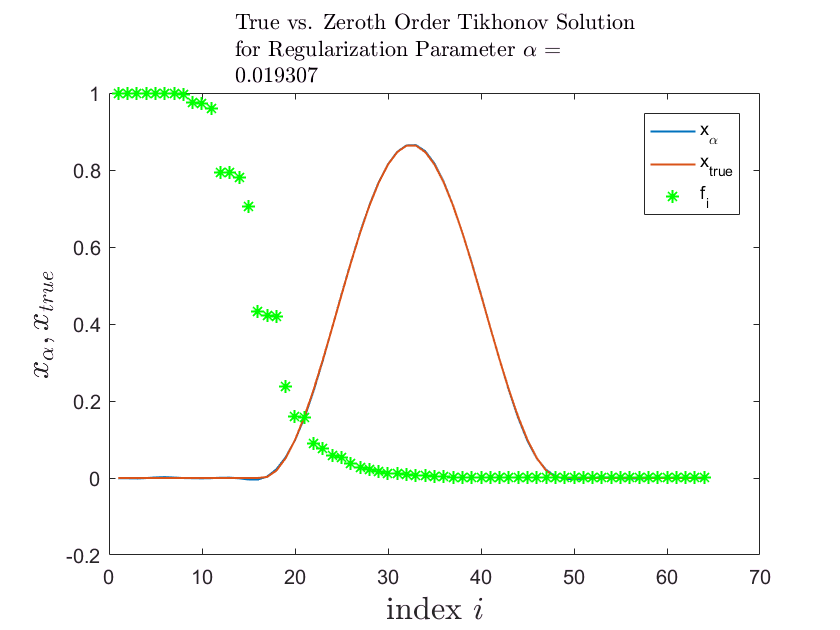

%Actually we don't really need to recalculate this if we just located the index of the optimal alpha, but oh well.
x_tikhonov_optimal = zeros(n,1);

filter_factors = singular_values.^2 ./ (singular_values.^2 + good_alpha^2);
    
    %The loop below calculates the Tikhonov solution for a given alpha using equation (2). 
    for ii = 1:n  
        x_tikhonov_optimal = x_tikhonov_optimal + filter_factors(ii) * (U(:, ii))' * y * V(:,ii) / singular_values(ii);
    end
    
plot1 = plot(1:64, x_tikhonov_optimal, 1:64, x_true, 1:64, filter_factors, 'g*', 'linewidth', 1);
xlabel('index $$i$$','FontSize',16,'interpreter','latex');
ylabel('$$x_{\alpha}, x_{true}$$','FontSize',16,'interpreter','latex');
title({'' 'True vs. Zeroth Order Tikhonov Solution' 'for Regularization Parameter $$\alpha$$ = ' num2str(good_alpha)},'Interpreter','latex')
names = {'x_{\alpha}' , 'x_{true}', 'f_i'};
legend(plot1,names, 'location', 'northeast')

The Tikhonov solution is so good that we can hardly even see it in our plot because it's hidden underneath the true solution.

## (b) 

Let $L_1$ and $L_2$ be finite difference smoothing operators with respect to the first and second derivatives of $x$ respectively. Then for $L = L_1$ or $L= L_2$ we want to find the vector $x$ that minimizes $\{||Gx-y||_2^2 + \alpha^2||L^TLx||_2^2\}$ for a given $\alpha$. As before it is not clear what we should choose for $\alpha$ but once $\alpha$ is chosen we can use the generalized singular value decomposition to find this minimizing $x$, which we denote $x_{\alpha}$. For $G$ and $L$, the generalized singular value decomposition will give unitary matrices $U$and $V$, a (usually) square matrix $X$, and nonnegative diagonal matrices $C$ and $S$ so that


$$G = UCX^*$$
    
$$L = VSX^*$$
 
$$\text{  and  }$$

$$C^*C + S^*S = I.$$
 

We then take $\lambda = \sqrt{\text{diag}(C^*C)}$, $\mu = \sqrt{\text{diag}(S^*S)}$ (where the square roots are to be understand as elementwise operations of vectors), and $\gamma_i = \lambda_i / \mu_i$. The Tikhonov solution is then


$$x_{\alpha} = \sum_{k+1}^n \frac{\gamma_i^2}{\gamma_i^2 + \alpha_i^2} \frac{u_{i-k}^*y}{\lambda_i}z_i \quad \quad (3)$$


 where since $G$ is a square matrix we have $k = 0$ and $z_i$ the $i^{th}$ columns of $X^{-*}$. Let $f_i = \frac{\gamma_i^2}{\gamma_i^2 + \alpha_i^2}$ and use the technique of setting $f_i = 1$ if $\gamma_i = \infty$ and $f_i = 0$ if it is the case that both $\lambda_i = 0$ and $\gamma_i^2 = 0$. 

First, let' use the first order smoothing operator $L_1$. Just as in part (a) we need to produce a lot of plots to get a good visual sense of what the solution approximations look like as alpha increases and so to watch a 'movie' see "HW4_Problem1b_Movie" (for $L_1$ and $L_2$). For the live script portion we again settle on a generally 'good' choice of alpha through residual norms and plot the result for this proposed optimal alpha. 

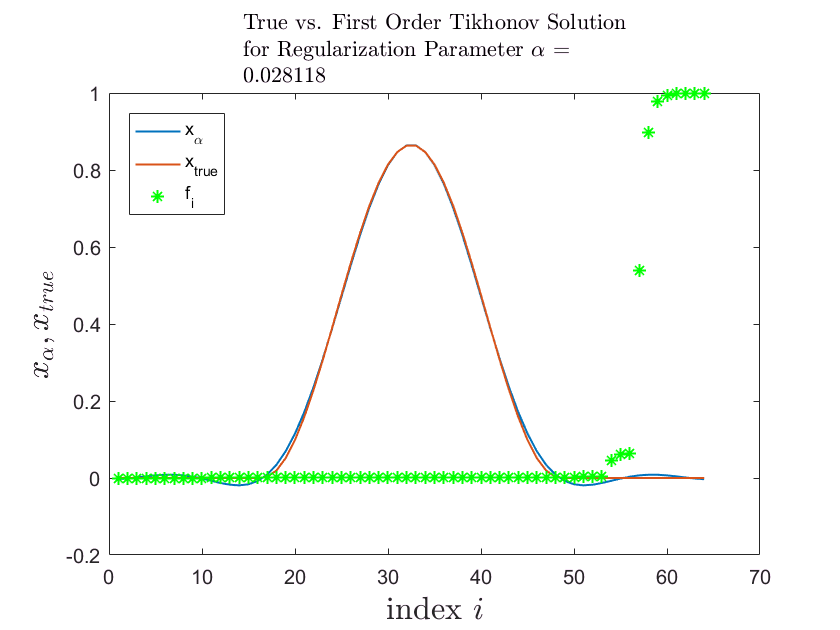

%Using the get_l.m function we apply the process above using L = L_1

[L,W] = get_l(n,1);
[U,V,X,C,S] = gsvd(G,full(L));
Z = (inv(X))';
lambdas = sqrt(diag(C'*C));
mus = sqrt(diag(S'*S));
generalized_singular_values = lambdas ./ mus;

x_tikhonov = zeros(n, length(alphas));

for jj = 1:length(alphas)
    
    filter_factors = zeros(1,n);
    
    %The loop below calculates the Tikhonov solution for a given alpha using equation (3).
    for ii = 1:n
        
        generalized_singular_value = lambdas(ii)/mus(ii);
        
        filter_factors(ii) = generalized_singular_value^2 / ...
            (generalized_singular_value^2 + alphas(jj)^2);
        
        if isfinite(filter_factors(ii)) == 0
            filter_factors(ii) = 1;
        end
        
        % Since G is square, we have k = 0
        % If a generalized singular value is not finite, set the corresponding filter factor to 1.

        x_tikhonov(:,jj) = x_tikhonov(:,jj) + ...
          filter_factors(ii) * (U(:, ii))' * y * Z(:,ii) / lambdas(ii);
      
    end
    
end

error_2norms = zeros(1,length(alphas));

for kk = 1:length(alphas)
    
    error_2norms(kk) = norm(x_tikhonov(:,kk) - x_true);
    
end

%We propose the optimal alpha to be the alpha that minimizes the norm of the residual.
good_alpha = alphas(find(error_2norms == min(error_2norms)));
x_tikhonov_optimal = zeros(n,1);

filter_factors = zeros(1,n);
    
%The loop below calculates the Tikhonov solution for a given alpha using equation (3).
for ii = 1:n
    
    generalized_singular_value = lambdas(ii)/mus(ii);
    
    filter_factors(ii) = generalized_singular_value^2 / ...
        (generalized_singular_value^2 + alphas(jj)^2);
    
    if isfinite(filter_factors(ii)) == 0
        filter_factors(ii) = 1;
    end
    
    % Since G is square, we have k = 0
    % If a generalized singular value is not finite, set the corresponding filter factor to 1.

    x_tikhonov_optimal = x_tikhonov_optimal + ...
      filter_factors(ii) * (U(:, ii))' * y * Z(:,ii) / lambdas(ii);
  
end
    
plot1 = plot(1:64, x_tikhonov_optimal, 1:64, x_true, 1:64, filter_factors, 'g*', 'linewidth', 1);
xlabel('index $$i$$','FontSize',16,'interpreter','latex');
ylabel('$$x_{\alpha}, x_{true}$$','FontSize',16,'interpreter','latex');
title({'' 'True vs. First Order Tikhonov Solution' 'for Regularization Parameter $$\alpha$$ = ' num2str(good_alpha)},'Interpreter','latex')
names = {'x_{\alpha}' , 'x_{true}', 'f_i'};
legend(plot1,names, 'location', 'northwest')

Next using $L_2$:

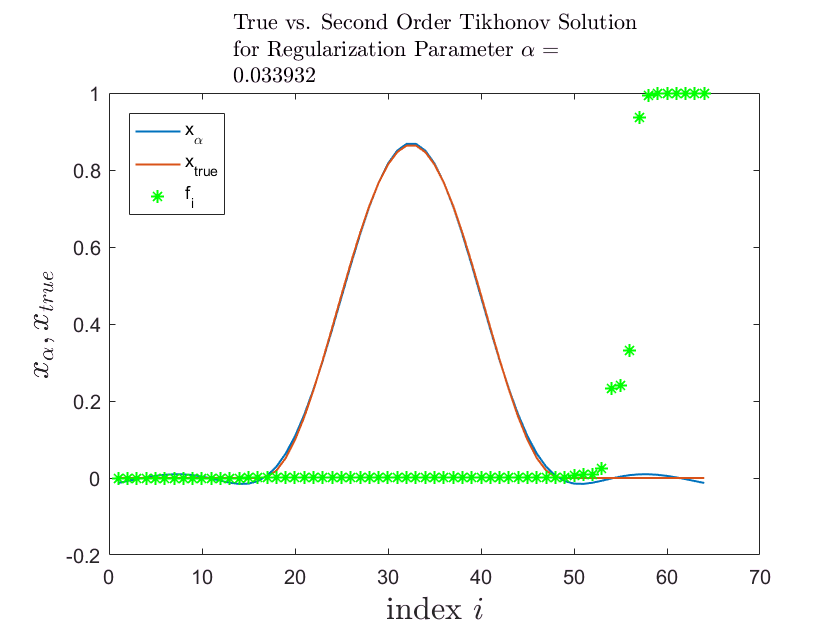

%Using the get_l.m function we apply the process above using L = L_2

[L,W] = get_l(n,2);
[U,V,X,C,S] = gsvd(G,full(L));
Z = (inv(X))';
lambdas = sqrt(diag(C'*C));
mus = sqrt(diag(S'*S));
generalized_singular_values = lambdas ./ mus;

x_tikhonov = zeros(n, length(alphas));

for jj = 1:length(alphas)
    
    filter_factors = zeros(1,n);
    
    %The loop below calculates the Tikhonov solution for a given alpha using equation (3).
    for ii = 1:n
        
        generalized_singular_value = lambdas(ii)/mus(ii);
        
        filter_factors(ii) = generalized_singular_value^2 / ...
            (generalized_singular_value^2 + alphas(jj)^2);
        
        if isfinite(filter_factors(ii)) == 0
            filter_factors(ii) = 1;
        end
        
        % Since G is square, we have k = 0
        % If a generalized singular value is not finite, set the corresponding filter factor to 1.

        x_tikhonov(:,jj) = x_tikhonov(:,jj) + ...
          filter_factors(ii) * (U(:, ii))' * y * Z(:,ii) / lambdas(ii);
      
    end
    
end

error_2norms = zeros(1,length(alphas));

for kk = 1:length(alphas)
    
    error_2norms(kk) = norm(x_tikhonov(:,kk) - x_true);
    
end

%We propose the optimal alpha to be the alpha that minimizes the norm of the residual.
good_alpha = alphas(find(error_2norms == min(error_2norms)));

x_tikhonov_optimal = zeros(n,1);

filter_factors = zeros(1,n);
    
%The loop below calculates the Tikhonov solution for a given alpha using equation (3).
for ii = 1:n
    
    generalized_singular_value = lambdas(ii)/mus(ii);
    
    filter_factors(ii) = generalized_singular_value^2 / ...
        (generalized_singular_value^2 + alphas(jj)^2);
    
    if isfinite(filter_factors(ii)) == 0
        filter_factors(ii) = 1;
    end
    
    % Since G is square, we have k = 0
    % If a generalized singular value is not finite, set the corresponding filter factor to 1.

    x_tikhonov_optimal = x_tikhonov_optimal + ...
      filter_factors(ii) * (U(:, ii))' * y * Z(:,ii) / lambdas(ii);
  
end
    
plot1 = plot(1:64, x_tikhonov_optimal, 1:64, x_true, 1:64, filter_factors, 'g*', 'linewidth', 1);
xlabel('index $$i$$','FontSize',16,'interpreter','latex');
ylabel('$$x_{\alpha}, x_{true}$$','FontSize',16,'interpreter','latex');
title({'' 'True vs. Second Order Tikhonov Solution' 'for Regularization Parameter $$\alpha$$ = ' num2str(good_alpha)},'Interpreter','latex')
names = {'x_{\alpha}' , 'x_{true}', 'f_i'};
legend(plot1,names, 'location', 'northwest')

## Problem 2

## (a)

For the first few $\alpha$ values the approximate solution oscillates excessively compared to the true solution (we could call this undersmoothing) while the approximate solution is nearly flat for the largest $\alpha$ choices when compared to the true solution (so we will call this oversmoothing). Although no choice of $\alpha$ gives a remarkably close approximation, a few intermediate choices at least recreate the behavior of the true solution. We can study this more closely in part (b).

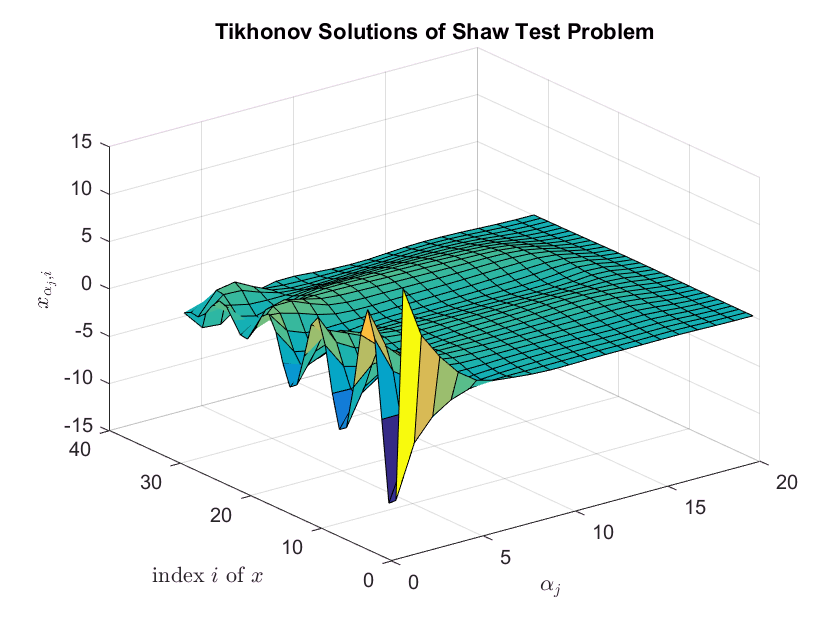

% Problem 2a

n=32;
[G,y_true,x_true] = shaw(n);
[U,S,V] = svd(G);
singular_values = diag(S);
y = y_true + 10^-3*randn(length(y_true),1); %simulate noisy data.

a = 20; %Number of alpha values we will use.
alphas = logspace(-5, 1, 20); %alphas log equally spaced.

X = zeros(n,length(alphas));

for jj = 1:length(alphas)
    
    %The filter factors change for each new choice of alpha. We use equation (1) to find them.
    filter_factors = singular_values.^2 ./ (singular_values.^2 + (alphas(jj))^2);
    
    %Loop below calculates zero order Tikhonov solution for a given alpha.
    for ii = 1:n
        
        X(:,jj) = X(:,jj) + ...
          filter_factors(ii) * (U(:, ii))' * y * V(:,ii) / singular_values(ii);
      
    end
    
end


surf(X);
xlabel('$$\alpha_j$$', 'interpreter', 'latex')
ylabel('index $$i$$ of $$x$$', 'interpreter', 'latex')
zlabel('$$x_{\alpha_j,i}$$', 'interpreter', 'latex')
title('Tikhonov Solutions of Shaw Test Problem')

## (b)

Even using up to $10^6$ different choices for $\alpha$, it is difficult to nominate any particular result as highly successful when compared to the accuracy we saw in Problem 1. It also takes a long time for computations (although part of this is probably my fault for using nested 'for loops' instead of vectorizing computations). Reducing the number of $\alpha$ values we try to $10^3$ helps but the 'optimal' value generally still varies between $\alpha \approx 0.0005$ and $\alpha \approx 0.01$ (or even more varied) with each running of the program. Although the corner of our L curves are not very sharp it seems that with each trial that the position on the L-curve corresponding to our calculated optimal $\alpha$ does actually lie near the corner (which occurs about where$||x_{\alpha}||_2 \approx 5.6$). So while our approximations may not be as accurate as in Problem 1, we at least have some consistency in finding a rough neighborhood for $\alpha$ for which the solution is not oversmoothed or undersmoothed.

%Problem 2b

n=32;
[G,y_true,x_true] = shaw(n);
[U,S,V] = svd(G);
singular_values = diag(S);
y = y_true + 10^-3*randn(length(y_true),1); %simulate noisy data.

alphas = logspace(-5, 1, 10^3); %100 alpha vlaues log equally spaced.

X = zeros(n,length(alphas));

for jj = 1:length(alphas)
    
    %The filter factors change for each new choice of alpha. We use equation (1) to find them.
    filter_factors = singular_values.^2 ./ (singular_values.^2 + (alphas(jj))^2);
    
    %Loop below calculates zero order Tikhonov solution for a given alpha.
    for ii = 1:n
        
        X(:,jj) = X(:,jj) + ...
          filter_factors(ii) * (U(:, ii))' * y * V(:,ii) / singular_values(ii);
      
    end
    
end

error_2norms = zeros(1,length(alphas));

for kk = 1:length(alphas)
    
    error_2norms(kk) = norm(X(:,kk) - x_true);
    
end

%We propose the optimal alpha to be the alpha that minimizes the norm of the residual.
good_alpha_index = find(error_2norms == min(error_2norms));
good_alpha = alphas(good_alpha_index)

good_alpha =    0.00049396


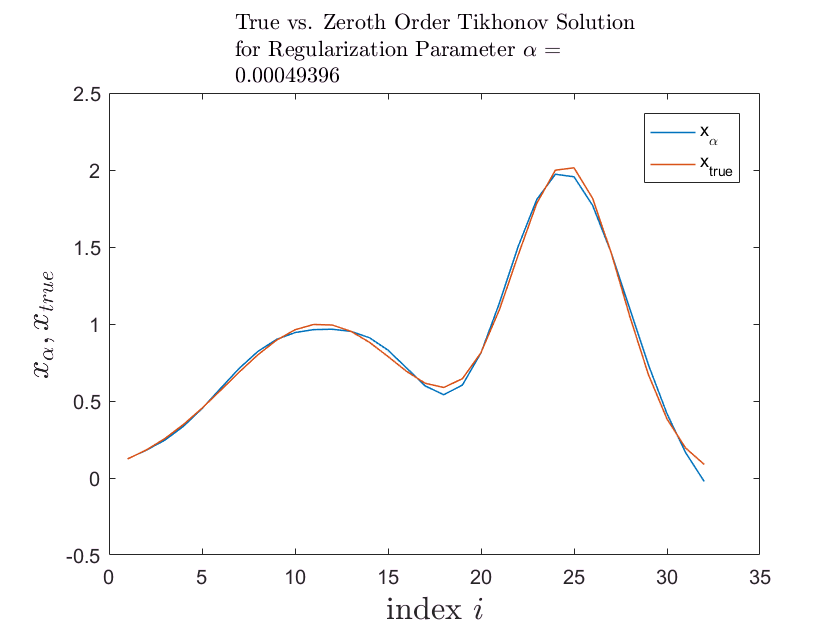


x_tikhonov_optimal = X(:,good_alpha_index);

plot1 = plot(1:n, x_tikhonov_optimal, 1:n, x_true, 'linewidth', 0.75);
xlabel('index $$i$$','FontSize',16,'interpreter','latex');
ylabel('$$x_{\alpha}, x_{true}$$','FontSize',16,'interpreter','latex');
title({'' 'True vs. Zeroth Order Tikhonov Solution' 'for Regularization Parameter $$\alpha$$ = ' num2str(good_alpha)},'Interpreter','latex')
names = {'x_{\alpha}' , 'x_{true}'};
legend(plot1,names, 'location', 'northeast')

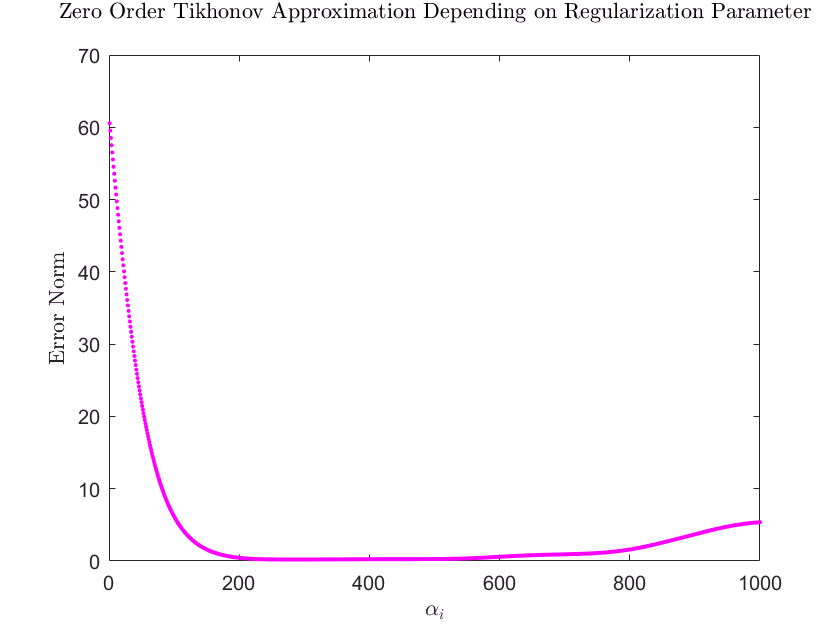


plot(error_2norms, 'm.', 'linewidth', 0.2)
xlabel('$$\alpha_i$$', 'interpreter', 'latex')
ylabel('Error Norm', 'interpreter', 'latex')
title({'Zero Order Tikhonov Approximation Depending on Regularization Parameter' ''},'Interpreter','latex')

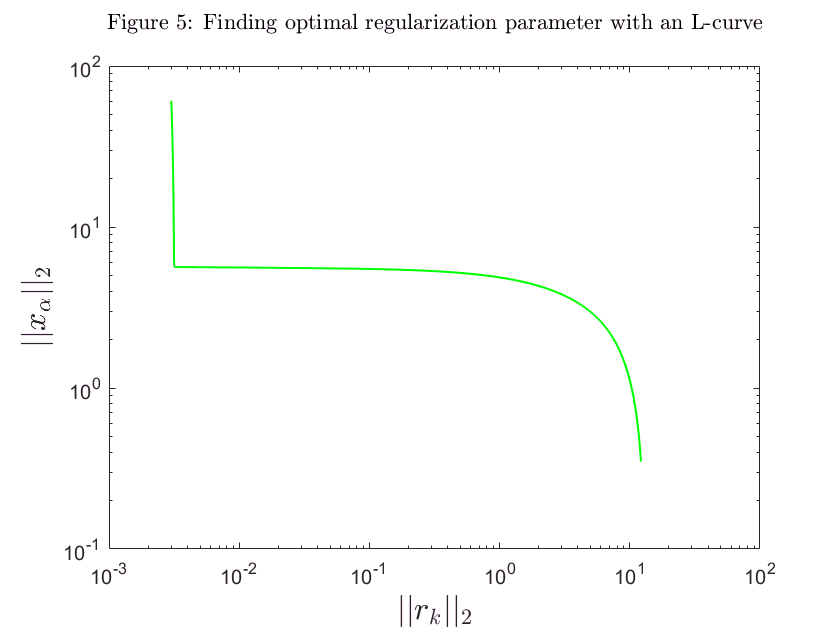



x_alpha_norms = zeros(1,length(alphas));
residual_2norms = zeros(1,length(alphas));

%Finding approximate solutions using truncated svd. It is simpler to to
%calculate x_k for k=1,...,64 even though we will only inspect k=2,..62.
for ii = 1:length(alphas)

   x_alpha_norms(ii) = norm(X(:,ii));
   residual_2norms(ii) = norm(G*X(:,ii) - y);
   
end

loglog(residual_2norms, x_alpha_norms, 'g', 'linewidth', 1);
xlabel('$$||r_k||_2$$','FontSize',16,'interpreter','latex');
ylabel('$$||x_{\alpha}||_2$$','FontSize',16,'interpreter','latex');
title({'' 'Figure 5: Finding optimal regularization parameter with an L-curve' ''},'Interpreter','latex')

## Problem 3

We used the 'wing.m' file to generate a model problem (using $n = 100$). The solution, which we denote $x_{true}$, has two discontinuities. To compute truncated SVD solutions for this problem, we use decompose $G$ as $G = U\Sigma V^*$. The truncated SVD solutions are then of the form 


$$x_k = V_k\Sigma_k^{-1}U_k^* = \sum_{i = 1}^k \frac{u_i^* y}{\sigma_i} v_i \quad \quad (4)$$


By plotting, we see although no approximation can recreate the discontinuities, but with some choices of $k$ we can at least mimic the behavior of the true soltuion and that the optimal $k$ is likely $k = 8$ or $k = 9$. The solution deteriorates dramatically starting with $k = 10$ and is never again a reasonable approximation. The progression can be viewed as a movie with "HW4_Problem3_Movie1.m", but we include some plots here as well. Looking at the singular values of $G$ we see that the magnitude of the singular values drops below $10^{-16}$ at about this point, which could help explain the 'blow up' of the solutions since the calculation for the TSVD relies on either inverting $S_k$ or dividing by the singular values. In either case this becomes problematic for singular values approximately 0. 

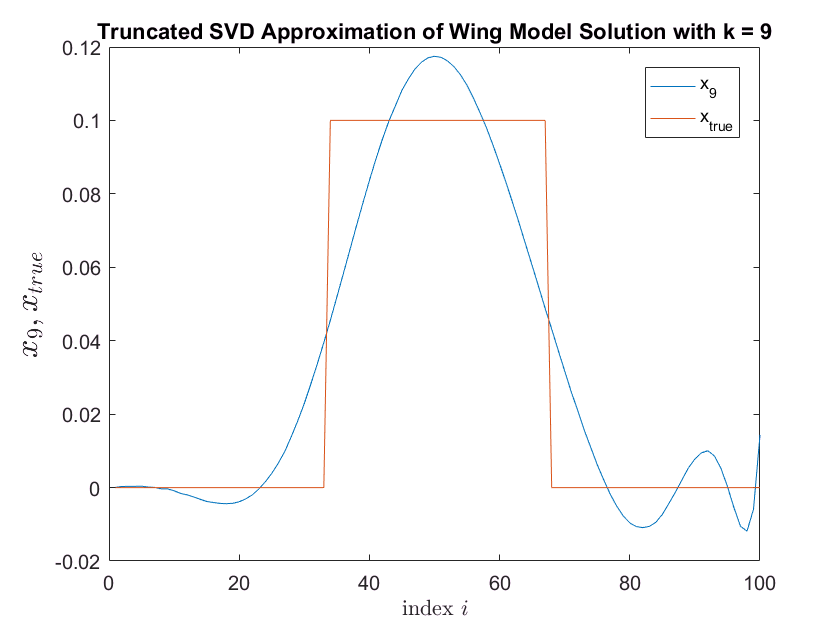

n = 100;
[G, y_true, x_true] = wing(n);
[U,S,V] = svd(G);

x_9 =  V(:,1:9)*inv(S(1:9,1:9))*(U(:,1:9))'*y_true;
plot1 = plot(1:n, x_9, 1:n, x_true);
xlabel('index $$i$$', 'interpreter', 'latex')
ylabel('$$x_9, x_{true}$$','FontSize',16, 'interpreter', 'latex')
names = {'x_{9}' , 'x_{true}'};
legend(plot1,names, 'location', 'northeast')
title({'Truncated SVD Approximation of Wing Model Solution with k = 9' })

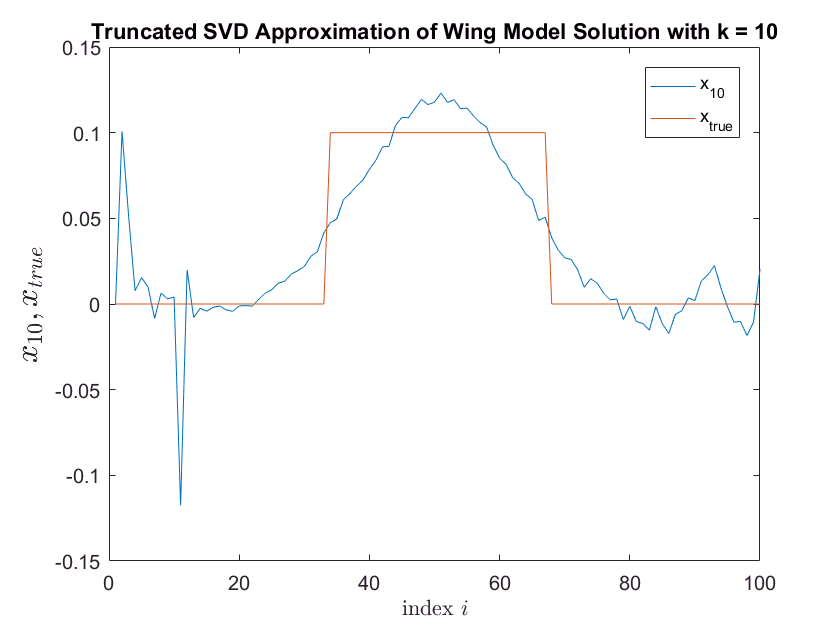

x_10 =  V(:,1:10)*inv(S(1:10,1:10))*(U(:,1:10))'*y_true;
plot1 = plot(1:n, x_10, 1:n, x_true);
xlabel('index $$i$$', 'interpreter', 'latex')
ylabel('$$x_{10} , x_{true}$$','FontSize',16, 'interpreter', 'latex')
names = {'x_{10}' , 'x_{true}'};
legend(plot1,names, 'location', 'northeast')
title({'Truncated SVD Approximation of Wing Model Solution with k = 10' })

When attempting to use zeroth order Tikhonov solution with various regularization parameters, it seems that really no choice of $\alpha$ is actually able to closely model the true solution (similar to what we saw for the TSVD). Very small choices of $\alpha$ allow the approximation to at least match the heights of the true solution somewhat. For larger $\alpha$ the solution is 'oversmoothed' and cannot even accomplish this. See "HW4_Problem3_Movie2.m" for a sample progression, but some sample plots are included here. It is likely that our difficulty arises from trying to approximate a discontinuous function with a continuous function (or a discretiation of a continuous function at least). The regularization parameter can control the overall smoothness of the approximation but I suppose discontinuities could be thought of as 'infinitely rough' parts of the graph. So no smoothing parameter can be small enough to truly recreate this.

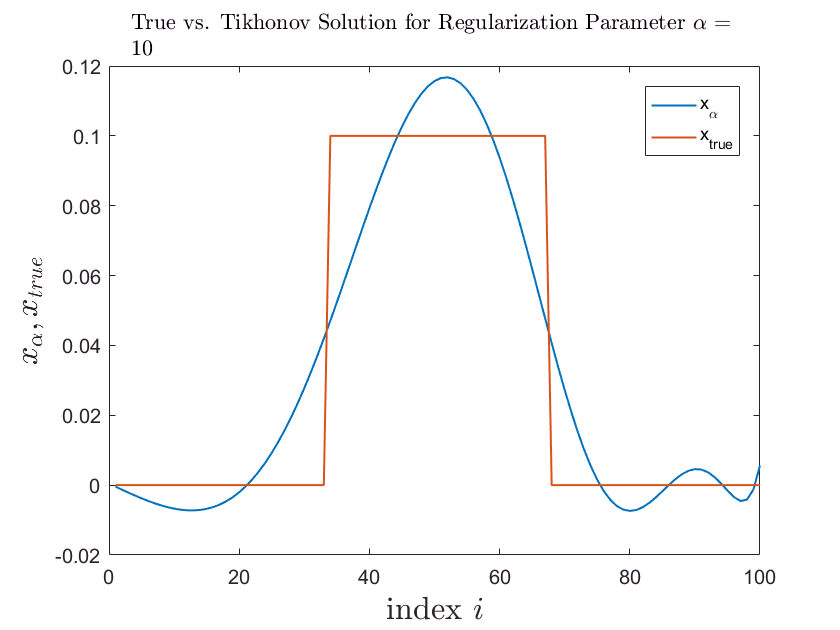

alpha = 10^-12;
x_tikhonov = zeros(n, 1);
singular_values = diag(S);

%The filter factors change for each new choice of alpha. We use equation (1) to find them.
filter_factors = singular_values.^2 ./ (singular_values.^2 + alpha^2);

%The loop below calculates the Tikhonov solution for a given alpha using equation (2). 
for ii = 1:n
    
    x_tikhonov = x_tikhonov + filter_factors(ii) * (U(:, ii))' * y_true * V(:,ii) / singular_values(ii);
  
end
plot1 = plot(1:n, x_tikhonov, 1:n, x_true, 'linewidth', 1);
xlabel('index $$i$$','FontSize',16,'interpreter','latex');
ylabel('$$x_{\alpha}, x_{true}$$','FontSize',16,'interpreter','latex');
title({'' 'True vs. Tikhonov Solution for Regularization Parameter $$\alpha$$ = ' num2str(alpha)},'Interpreter','latex')
names = {'x_{\alpha}' , 'x_{true}'};
legend(plot1,names, 'location', 'northeast')

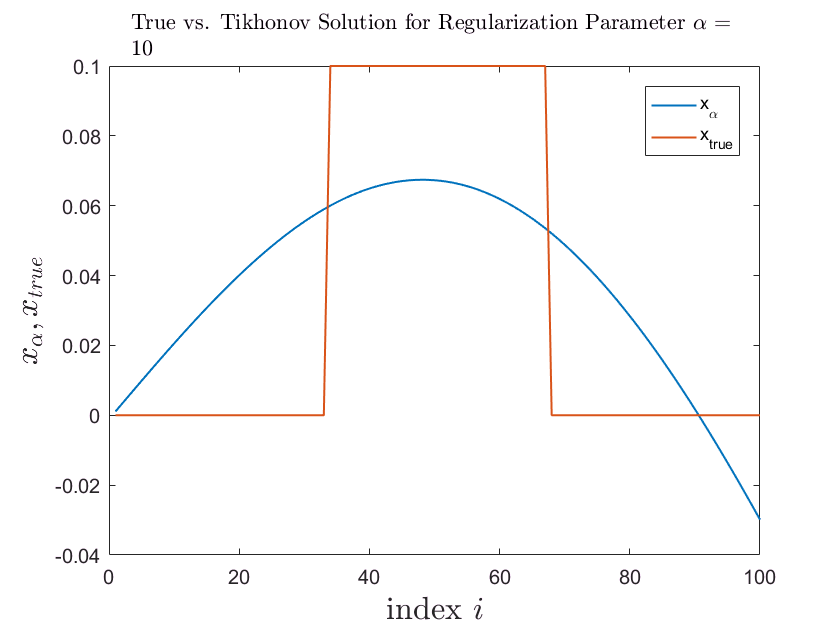


alpha = 10^-3;
x_tikhonov = zeros(n, 1);

%The filter factors change for each new choice of alpha. We use equation (1) to find them.
filter_factors = singular_values.^2 ./ (singular_values.^2 + alpha^2);

%The loop below calculates the Tikhonov solution for a given alpha using equation (2). 
for ii = 1:n
    
    x_tikhonov = x_tikhonov + ...
      filter_factors(ii) * (U(:, ii))' * y_true * V(:,ii) / singular_values(ii);
  
end

plot1 = plot(1:n, x_tikhonov, 1:n, x_true, 'linewidth', 1);
xlabel('index $$i$$','FontSize',16,'interpreter','latex');
ylabel('$$x_{\alpha}, x_{true}$$','FontSize',16,'interpreter','latex');
title({'' 'True vs. Tikhonov Solution for Regularization Parameter $$\alpha$$ = ' num2str(alpha)},'Interpreter','latex')
names = {'x_{\alpha}' , 'x_{true}'};
legend(plot1,names, 'location', 'northeast')